# Laboratorium nr. 11

Przetwarzanie sygnałów cyfrowych

Filip Pasternak, grupa lab. 7, piątek 18:30

## Zadanie 1

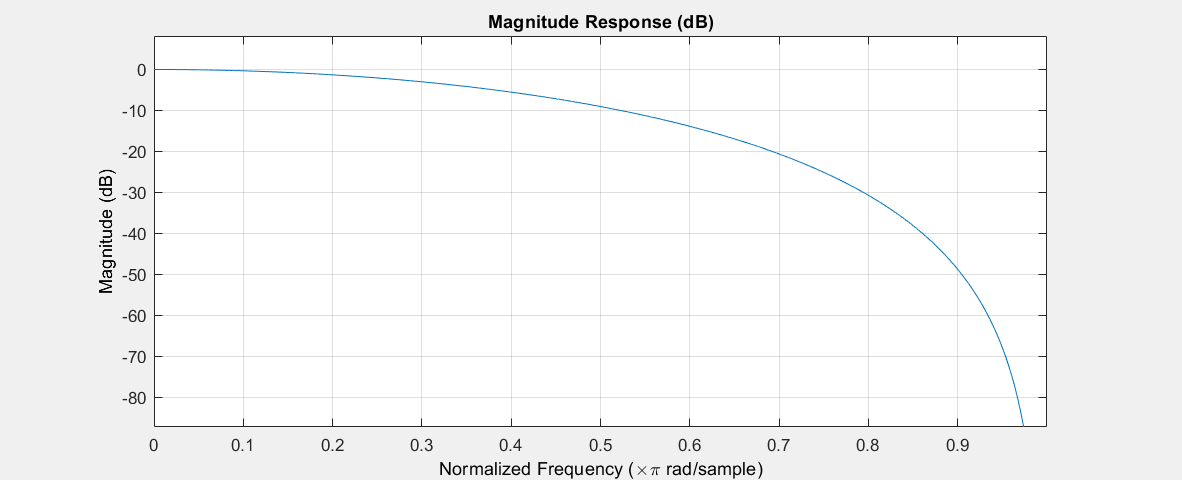

clear all

%1
[b,a] = maxflat(4,1,0.3); 
fvtool(b,a);

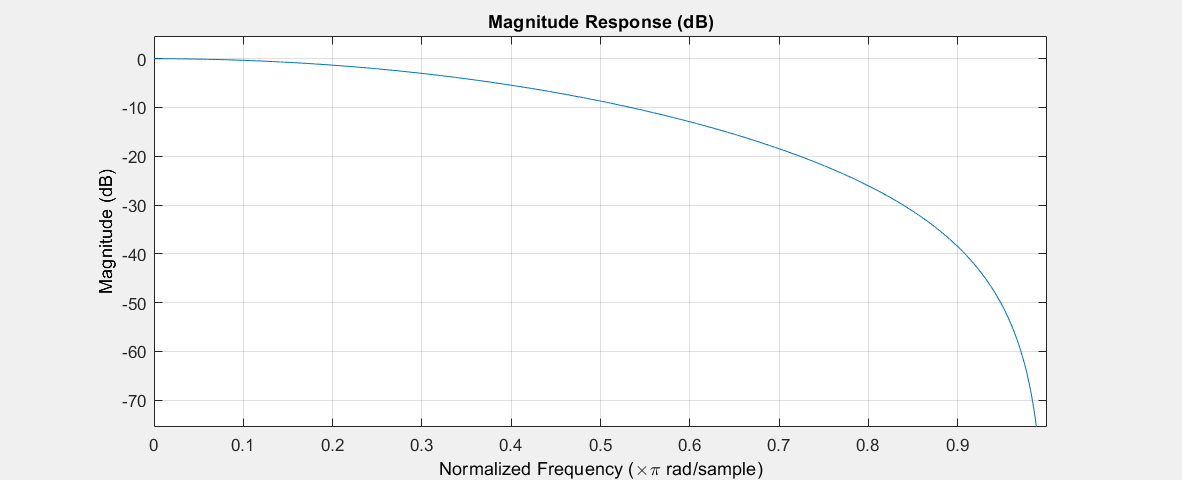


%2
[b, a] = maxflat(4,'sym',0.3);
fvtool(b,a);

## Zadanie 2

clear all

b = [1 -0.5];
a = [1 -2];
act_flag1 = isstable(b,a)

act_flag1 = logical
   0


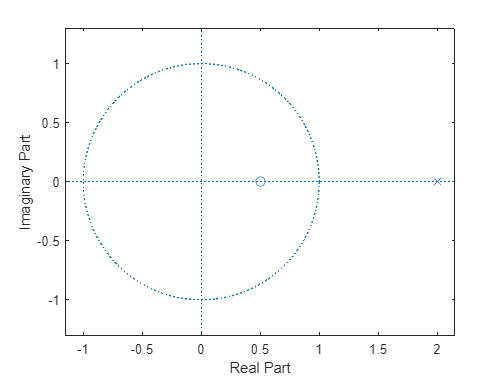

zplane(b,a)

Wynik flag = 0 oznacza, że filtr jest niestabilny

## Zadanie 3

clear all

b = [1 -0.1];
a = [-1 -0.1];
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


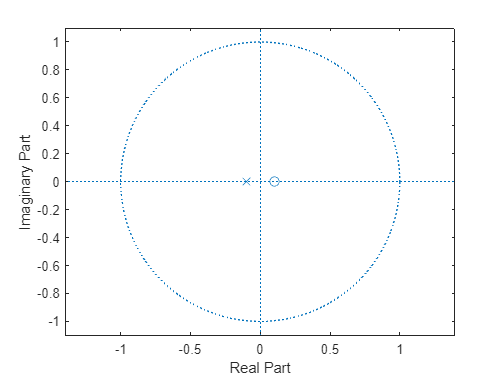

zplane(b,a)

Wynik flag = 1 oznacza, że filtr jest stabilny

## Zadanie 4

clear all

b = [0.9 -0.8];
a = [-0.9 -0.8];
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


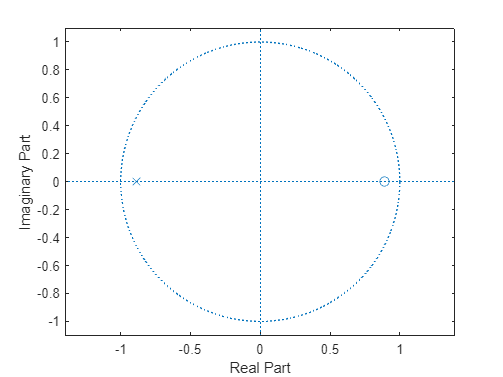

zplane(b,a)

Wynik flag = 1 oznacza, że filtr jest stabilny

## Zadanie 5

clear all

b = [0.9 -0.8 1 1];
a = [-0.9 -0.8 -1];
act_flag1 = isstable(b,a)

act_flag1 = logical
   0


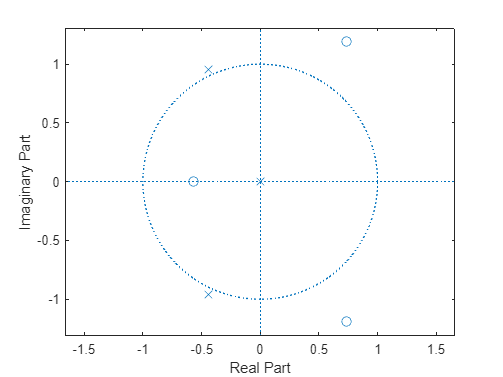

zplane(b,a)

Wynik flag = 0 oznacza, że filtr jest niestabilny

## Zadanie 6

m = [0 0 1 1 1 0 1 1 0 0];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1]; 
[b,a] = yulewalk(10,f,m); 

act_flag1 = isstable(b,a)

act_flag1 = logical
   1


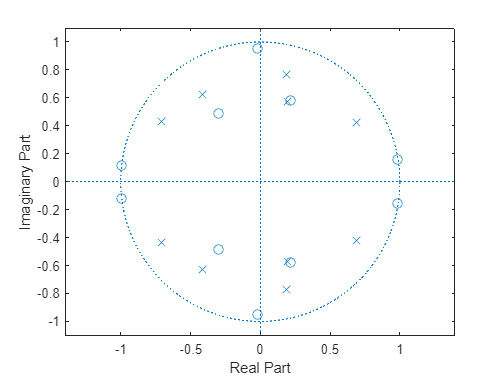

zplane(b,a)

Wynik flag = 1 oznacza, że filtr jest stabilny

## Zadanie 7

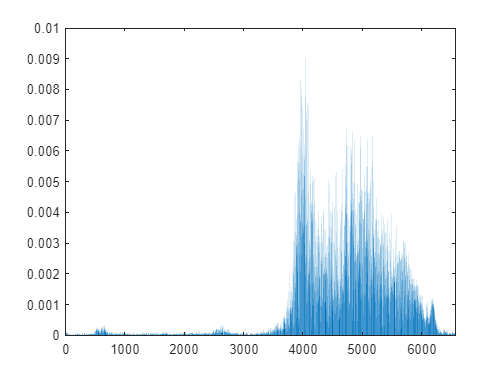

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

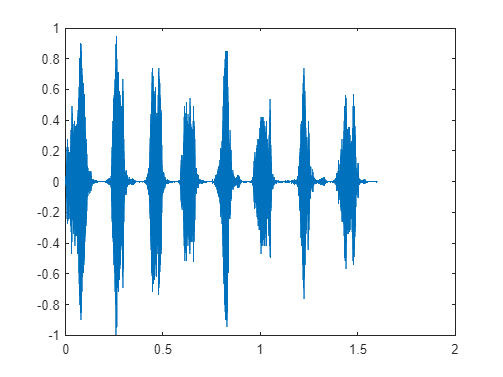

plot(t,y); 

## Zadanie 8

figure;
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y)); 
xfft=xfft/13129; 
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]); 

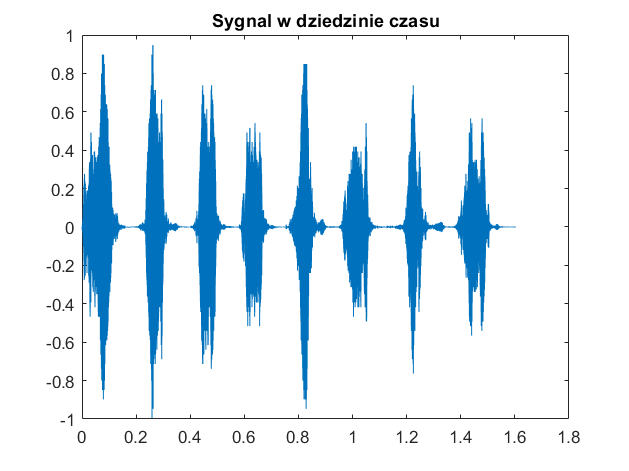

plot(t,y);
title('Sygnal w dziedzinie czasu');

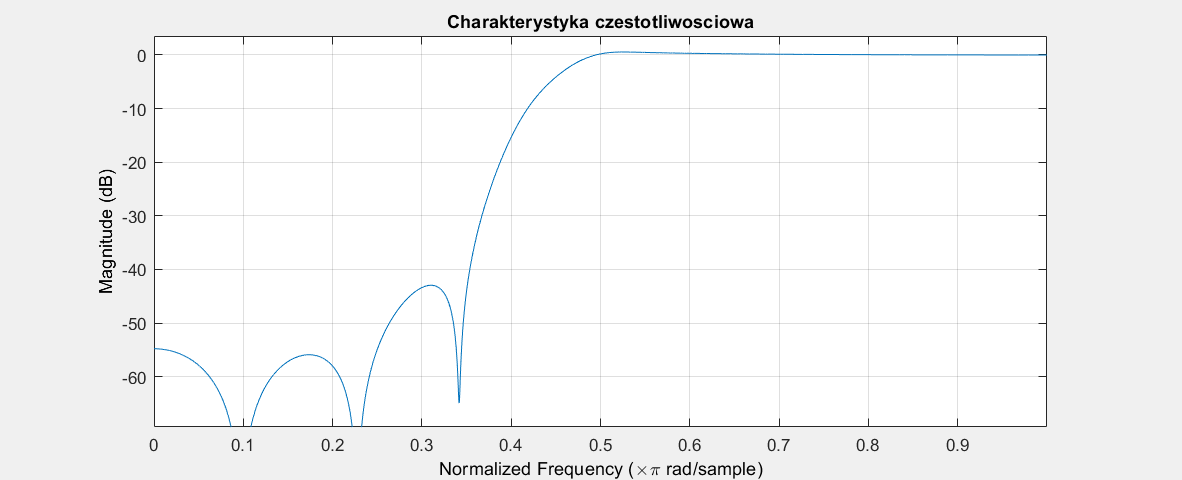


m = [0   0   0   0   0   1   1   1   1 1]; 
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1]; 
[b,a] = yulewalk(10,f,m);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

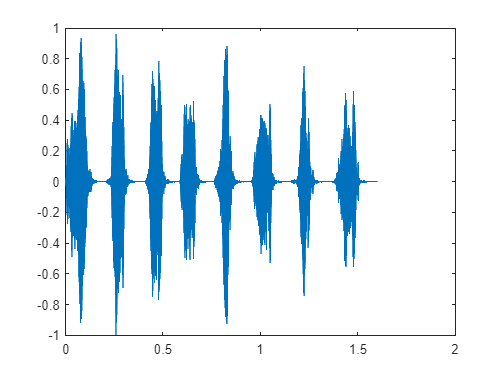


out = filter(b,a,y);
plot(t, out); 

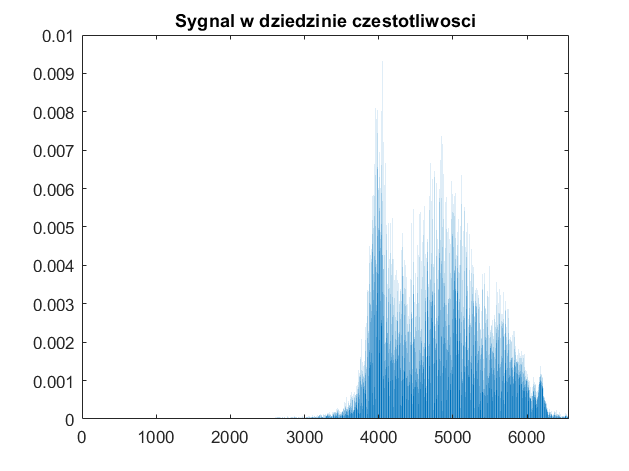

xfft=abs(fft(out)); 
xfft=xfft/13129; 
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564));  
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

## Zadanie 9